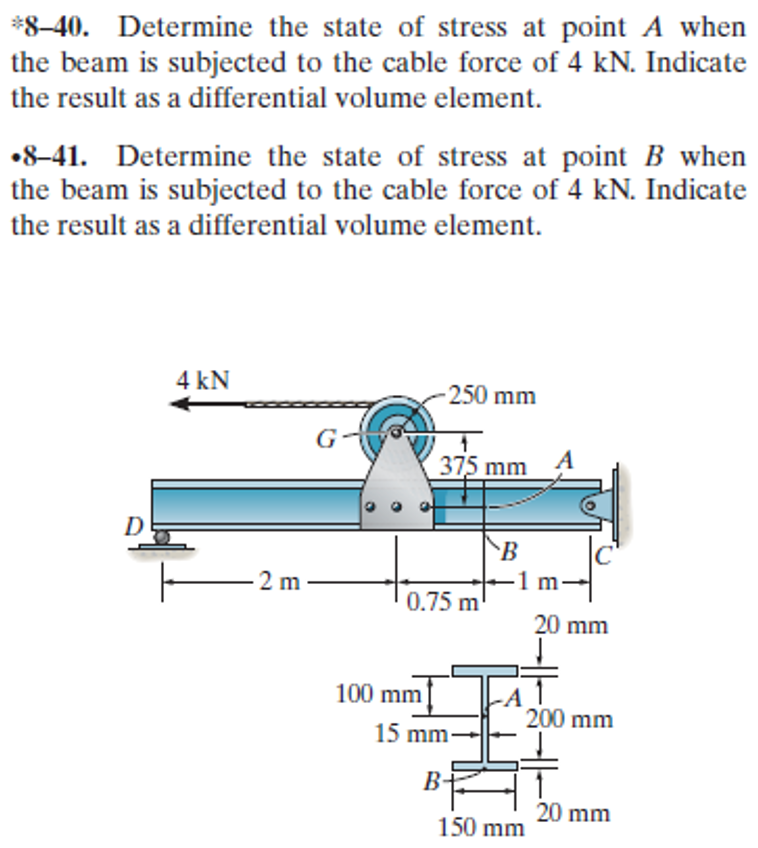

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-8-problem-40P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-8-problem-40P-solution-9780136022305) (problem 6-40)

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-8-problem-41P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-8-problem-41P-solution-9780136022305) (problem 6-41)

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

Fg = 4*u.kN;
dg = (250+375)*u.mm;
Mg = rewrite(Fg*dg, [u.kN u.m]);
[sigmax sigmay tauxy] = deal(default_struct('a', 'b'));

# beam

b = beam;
b = b.add('reaction', 'force', 'Rd', 0);
b = b.add('reaction', 'force', 'Rc', 3.75*u.m);
b = b.add('concentrated', 'moment', Mg, 2*u.m);
b.L = 3.75*u.m;

# section properties

yc = [110 50 -50 -110]*u.mm;
Ac = [150*20 15*100 15*100 150*20]*u.mm^2;
Ic = [150*20^3 15*100^3 15*100^3 150*20^3]/12*u.mm^4;
[yn Qn In] = beam.neutral_axis(yc, Ac, Ic);
b.I = rewrite(sum(In), u.m);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{312500\,x\,\left(39\,m^{2}-8\,x^{2}\right)}{1863\,\text{E}}\,\frac{\mathrm{kN}}{m^{4}} & \text{ if }x\leq 2\,m\\ \frac{312500\,\left(4\,x-15\,m\right)\,\left(2\,x^{2}-15\,x\,m+24\,m^{2}\right)}{1863\,\text{E}}\,\frac{\mathrm{kN}}{m^{4}} & \text{ if }2\,m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{312500\,\left(13\,m^{2}-8\,x^{2}\right)}{621\,\text{E}}\,\frac{\mathrm{kN}}{m^{4}} & \text{ if }x\leq 2\,m\\ \frac{312500\,\left(8\,x^{2}-60\,x\,m+107\,m^{2}\right)}{621\,\text{E}}\,\frac{\mathrm{kN}}{m^{4}} & \text{ if }2\,m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} \frac{2\,x}{3}\,\mathrm{kN} & \text{ if }x\leq 2\,m\\ \frac{4\,x-15\,m}{6}\,\mathrm{kN} & \text{ if }2\,m<x \end{array}\right.$$

v

$$v(x) = \frac{2}{3}\,\mathrm{kN}$$

w

$$w(x) = 0$$

# reactions and hinges

ra_vpa = vpa(ra, 3)

$$ra\_vpa = \left(\begin{array}{cc} \mathrm{Rc} & -0.667\,\mathrm{kN}\\ \mathrm{Rd} & 0.667\,\mathrm{kN} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

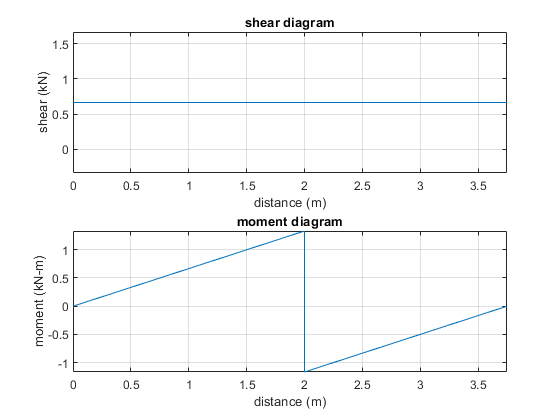

beam.shear_moment(m, v, [0 b.L], {'kN' 'm'});

# state of stress at point A

% axial stress
A = sum(Ac);
sigma_axial.a = rewrite(Fg/A, u.MPa);
sigma_axial_a = vpa(sigma_axial.a, 3) %#ok<NASGU> 

$$sigma\_axial\_a = 0.444\,\mathrm{MPa}$$

% bending stress
M.a = m(2.75*u.m);
Y.a = sym(0);
b.I = rewrite(b.I, u.mm);
sigma_bending.a = rewrite(-M.a*Y.a/b.I, u.MPa);
sigma_bending_a = sigma_bending.a %#ok<NASGU> 

$$sigma\_bending\_a = 0$$

% normal stress in the x-direction
sigmax.a = sigma_axial.a+sigma_bending.a;
sigmax_a = vpa(sigmax.a, 3) %#ok<NASGU> 

$$sigmax\_a = 0.444\,\mathrm{MPa}$$

% normal stress in the y-direction
sigmay.a = sym(0);
sigmay_a = sigmay.a

$$sigmay\_a = 0$$

% shear stress
V.a = -v(2.75*u.m);
Q.a = sum(Qn(1:2));
t.a = 15*u.mm;
tauxy.a = rewrite(V.a*Q.a/(b.I*t.a), u.MPa);
tauxy_a = vpa(tauxy.a, 3) %#ok<NASGU> 

$$tauxy\_a = -0.217\,\mathrm{MPa}$$

# state of stress at point B

% axial stress
sigma_axial.b = rewrite(Fg/A, u.MPa);
sigma_axial_b = vpa(sigma_axial.b, 3) %#ok<NASGU> 

$$sigma\_axial\_b = 0.444\,\mathrm{MPa}$$

% bending stress
M.b = m(2.75*u.m);
Y.b = -120*u.mm;
sigma_bending.b = rewrite(-M.b*Y.b/b.I, u.MPa);
sigma_bending_b = vpa(sigma_bending.b, 3) %#ok<NASGU> 

$$sigma\_bending\_b = -0.966\,\mathrm{MPa}$$

% normal stress in the x-direction
sigmax.b = sigma_axial.b+sigma_bending.b;
sigmax_b = vpa(sigmax.b, 3) %#ok<NASGU> 

$$sigmax\_b = -0.522\,\mathrm{MPa}$$

% normal stress in the y-direction
sigmay.b = sym(0);
sigmay_b = sigmay.b

$$sigmay\_b = 0$$

% shear stress
V.b = -v(2.75*u.m);
Q.b = sym(0);
t.b = 15*u.mm;
tauxy.b = rewrite(V.b*Q.b/(b.I*t.b), u.MPa);
tauxy_b = tauxy.b %#ok<NASGU> 

$$tauxy\_b = 0$$

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear sigma_axial_a sigma_bending_a sigmax_a tauxy_a;
clear sigma_axial_b sigma_bending_b sigmax_b tauxy_b;